**Log: **

15-Dec-2020;SWC. Train basic model with more images to see if any difference.

close all 
clear all 
clc 

## **1) Load Data**

path = fullfile('c:\','Users','chong','OneDrive - University of Birmingham','Year 4','RP - Machine Learning', 'TrainingData-combined');

% load images into data store; images stored in sub-folders according to category label 
% so can use as label source.
imds = imageDatastore(path, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
imds.ReadSize = numpartitions(imds); 
imds.ReadFcn = @(loc)imresize(imread(loc), [128,128]);

% count the number of images available in each category
tbl_count = countEachLabel(imds)

tbl_count = 3×2 table
       Label       Count
    ___________    _____

    Coalescence     160 
    Doublet         262 
    Singlet         198 


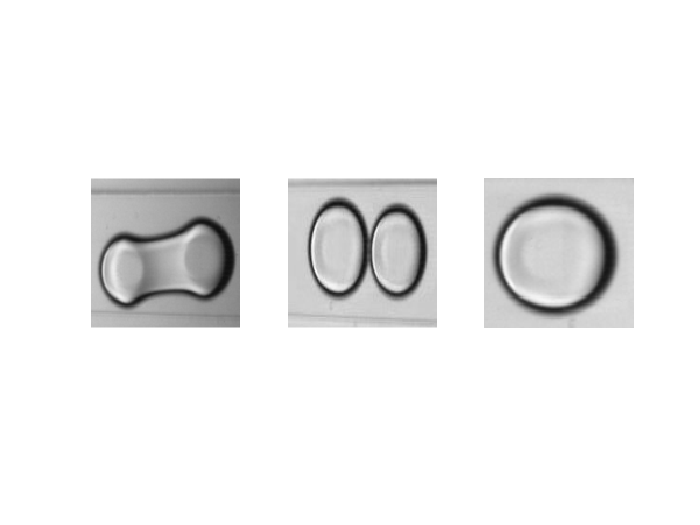

% load some images to check
sample = splitEachLabel(imds, 1, 'randomized'); 
for i = 1:length(tbl_count.Label)
    subplot(1,length(tbl_count.Label),i); 
    imshow(sample.readimage(i))
end

## 2) Data Preparation

% use split ratio: 70% training, 30% validation
[train_set, validation_set] = splitEachLabel(imds, 0.7, 'randomized');

% use split ratio: 80% training, 10% validation, 10% test
% [train_set, validation_set, test_set] = splitEachLabel(imds, 0.8, 0.1, 'randomized');

## 3) Create Visual Vocabulary - Feature Extraction

This is accomplished with a single call to *bagOfFeatures* function: 

- extracts SURF features from all images in all image categories 

- constructs the visual vocabulary by reducing the number of features through quantisation of feature space using K-menas clustering

*Note: bagOfFeatures* *object provides an encode method for counting the visual word occurances in an image. It produced a histogram that becomes a new and reduced representation of an image.*

bag = bagOfFeatures(train_set,'VocabularySize',500);

Creating Bag-Of-Features.
-------------------------
* Image category 1: Coalescence
* Image category 2: Doublet
* Image category 3: Singlet
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 434 images...done. Extracted 444416 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 1 has the least number of strongest features: 91750.
** Using the strongest 91750 features from each of the other image categories.

* Using K-Means clustering to create a 500 word visual vocabulary.
* Number of features          : 275250
* Number of clusters (K)      : 500

* Initializing cluster centers...100.00%.
* Clustering...completed 20/100 iterations (~2.23 seconds/iteration)...converged in 20 iterations.

* F

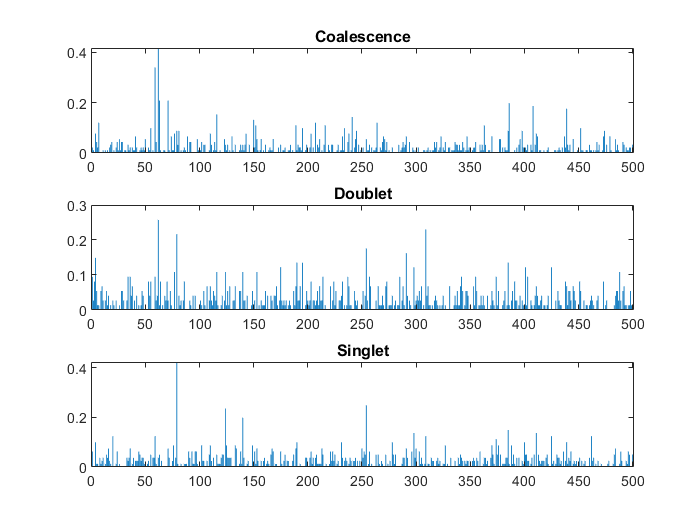

% load some images to check histogram
for i = 1:length(tbl_count.Label)
    subplot(length(tbl_count.Label),1,i); 
    featureVector = encode(bag, sample.readimage(i));
    bar(featureVector); title(char(tbl_count.Label(i)));
end

## 4) Train Classification Model: multiclass linear SVM classifier (using all default values)

classifier = trainImageCategoryClassifier(train_set, bag); 

Training an image category classifier for 3 categories.
--------------------------------------------------------
* Category 1: Coalescence
* Category 2: Doublet
* Category 3: Singlet

* Encoding features for 434 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



## 5) Evaluate Classifier Performance

% santiy check: test with training set:
% this should produce a near perfect confusion matrix
confMatrix_check = evaluate(classifier, train_set);

Evaluating image category classifier for 3 categories.
-------------------------------------------------------

* Category 1: Coalescence
* Category 2: Doublet
* Category 3: Singlet

* Evaluating 434 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                             PREDICTED
KNOWN          | Coalescence   Doublet   Singlet   
---------------------------------------------------
Coalescence    | 0.89          0.11      0.00      
Doublet        | 0.07          0.93      0.01      
Singlet        | 0.00          0.01      0.99      

* Average Accuracy is 0.94.



% then, test with validation set
confMatrix_valid = evaluate(classifier, validation_set);

Evaluating image category classifier for 3 categories.
-------------------------------------------------------

* Category 1: Coalescence
* Category 2: Doublet
* Category 3: Singlet

* Evaluating 186 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                             PREDICTED
KNOWN          | Coalescence   Doublet   Singlet   
---------------------------------------------------
Coalescence    | 0.85          0.15      0.00      
Doublet        | 0.10          0.90      0.00      
Singlet        | 0.05          0.07      0.88      

* Average Accuracy is 0.88.



% compute average accuracy
fprintf('Average accuracy = %.2f%%', mean(diag(confMatrix_valid))*100)

Average accuracy = 87.81%